clc
clear
close all


#### Some key references

[https://csml.berkeley.edu/Notes/ME280A.pdf](https://csml.berkeley.edu/Notes/ME280A.pdf) - ME280A notes (Intro to FEM, Papadopoulos)

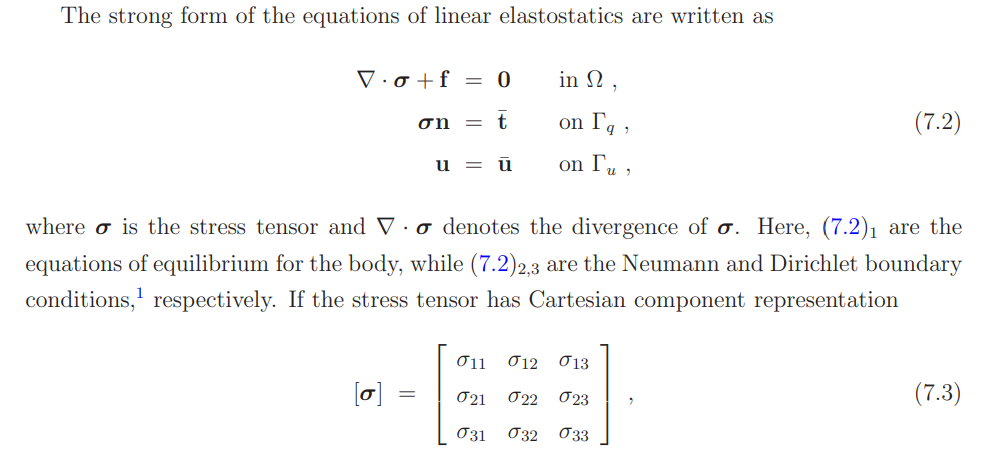

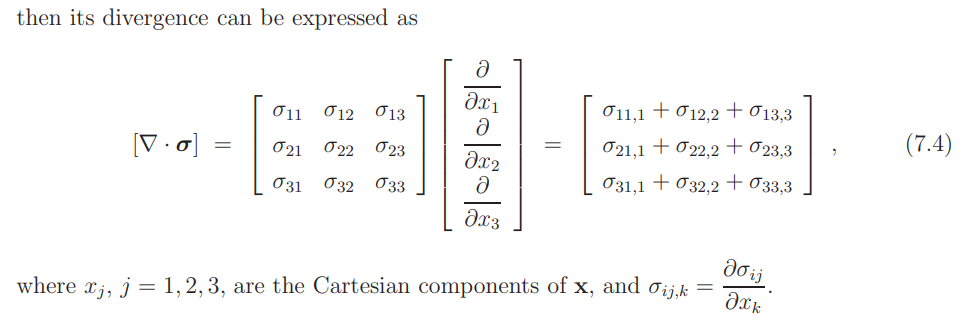

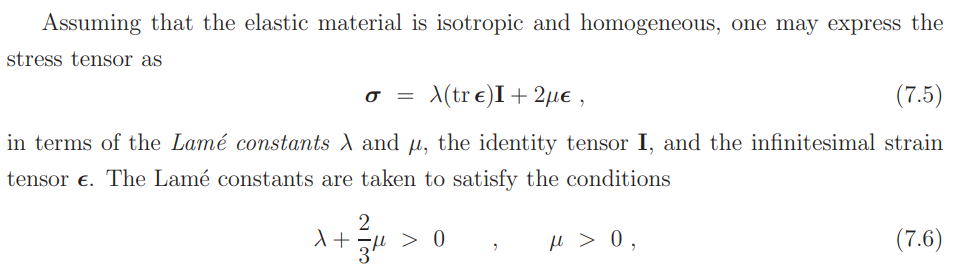

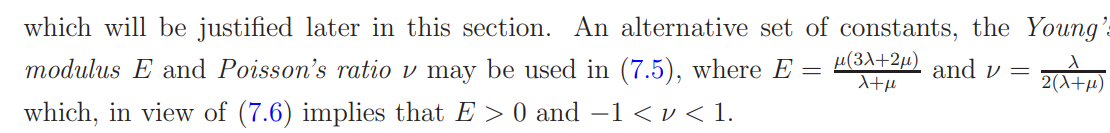

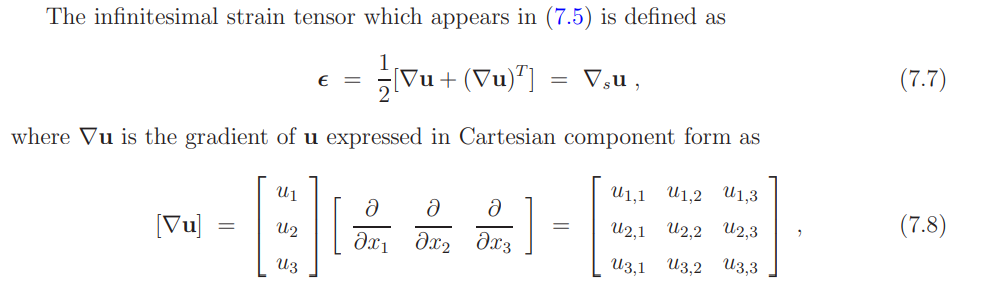

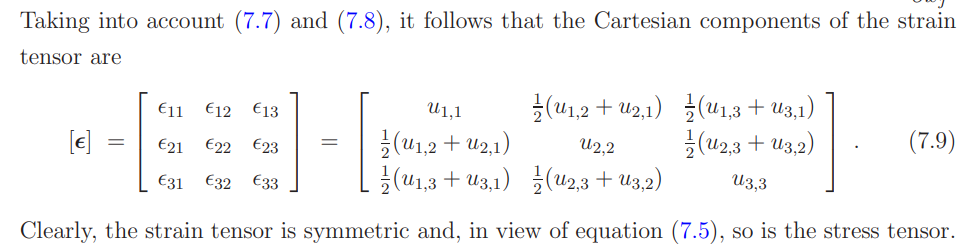

Converting strong form into the weak form the following weak form can be obrained through integration by parts, divergence theorem, and setting assuming that kinematic constrained is satisfied directly (variation is zero at the Dirichlet boundary).

  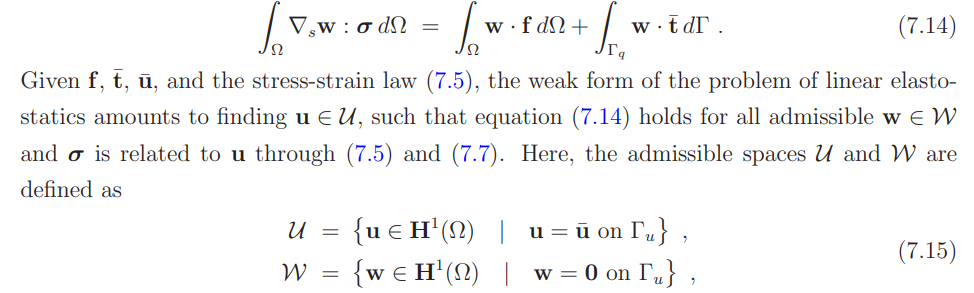

We can then rewrite the matrix forms as vector forms for practical implementation

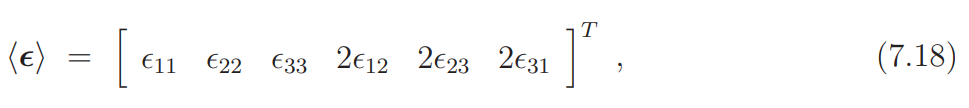

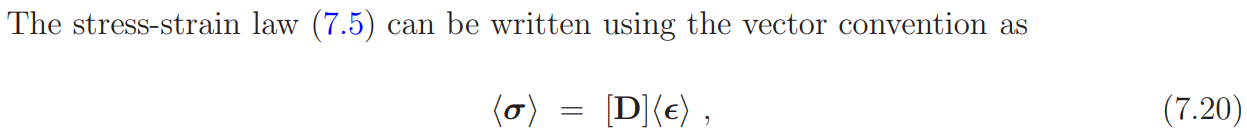

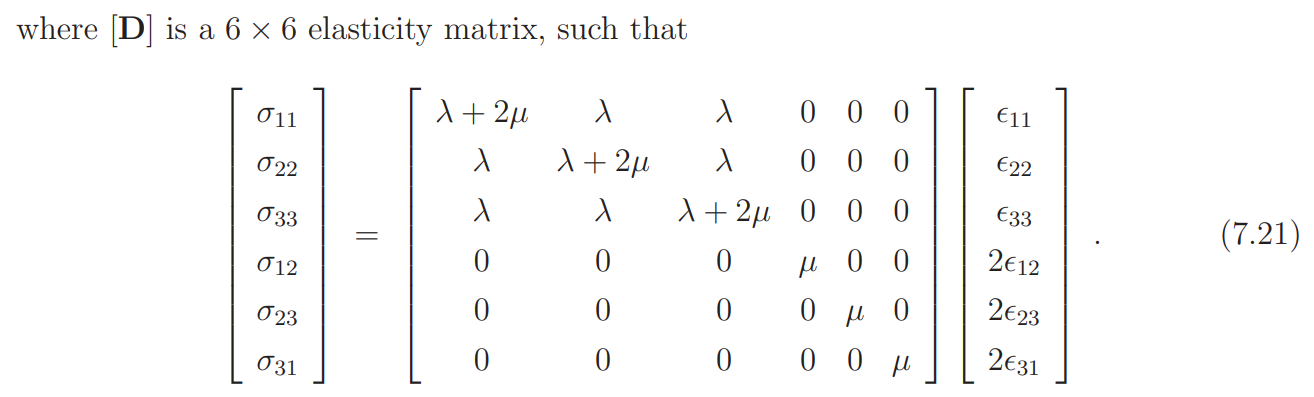

Reducing to plane strain (ex. very wide dam) and plain stress (ex. thin sheet) conditions:

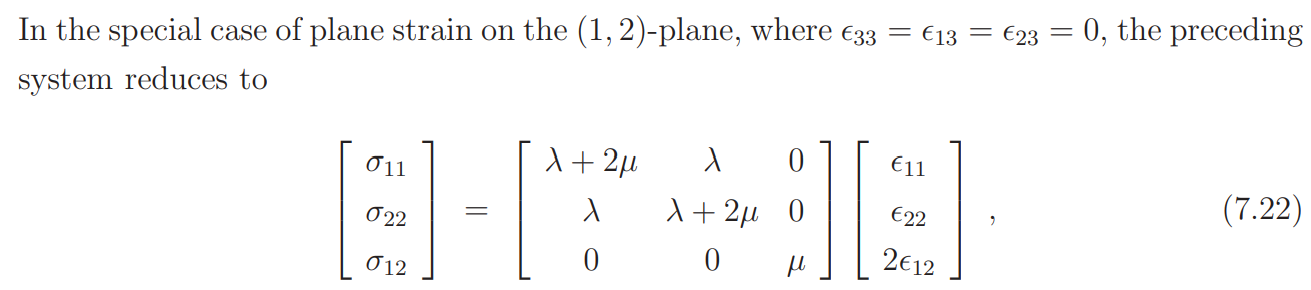

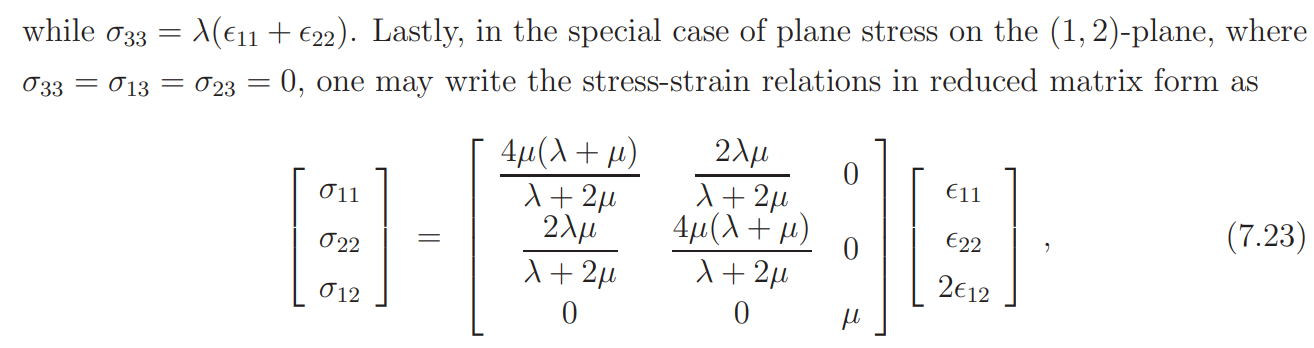

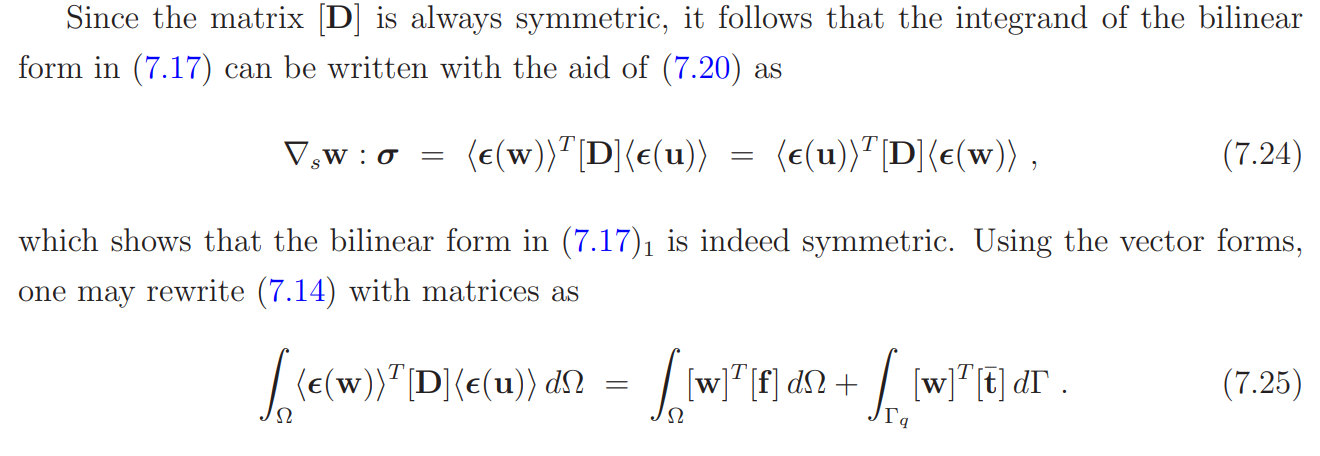

 Some further additional notes on the space discretization - Galerkin approximation: 

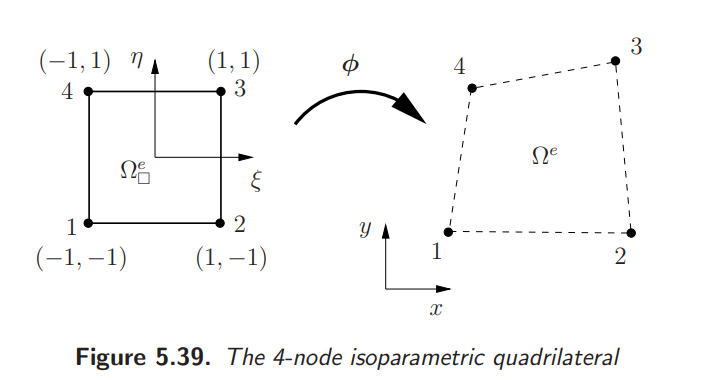

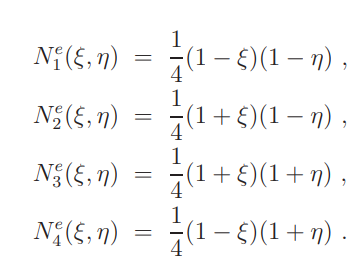

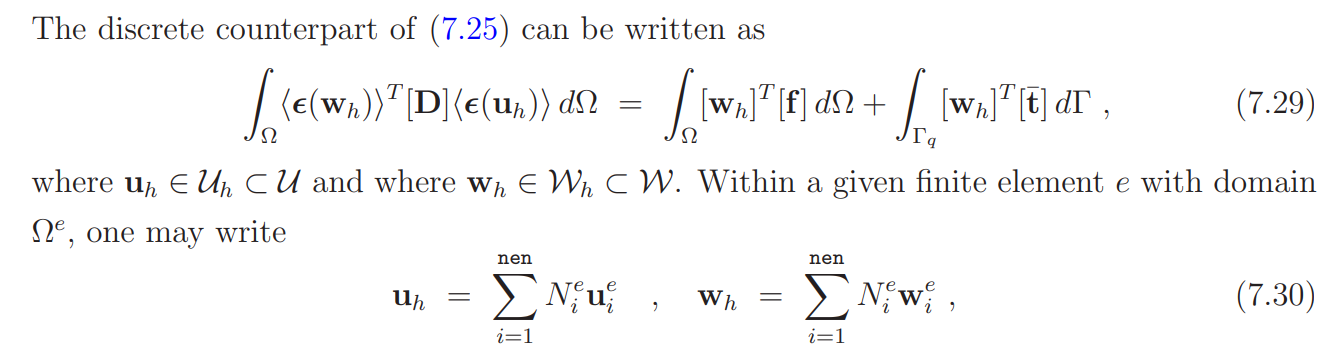

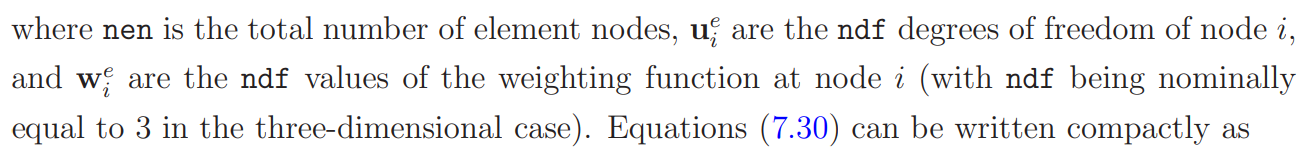

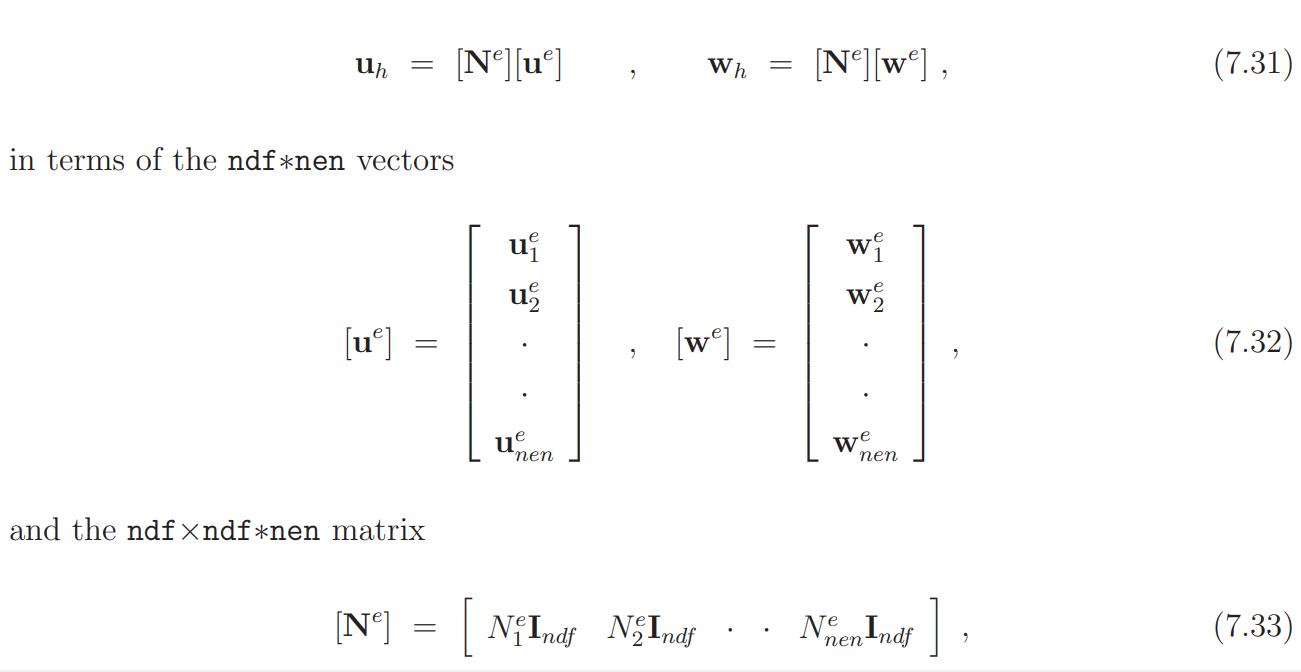

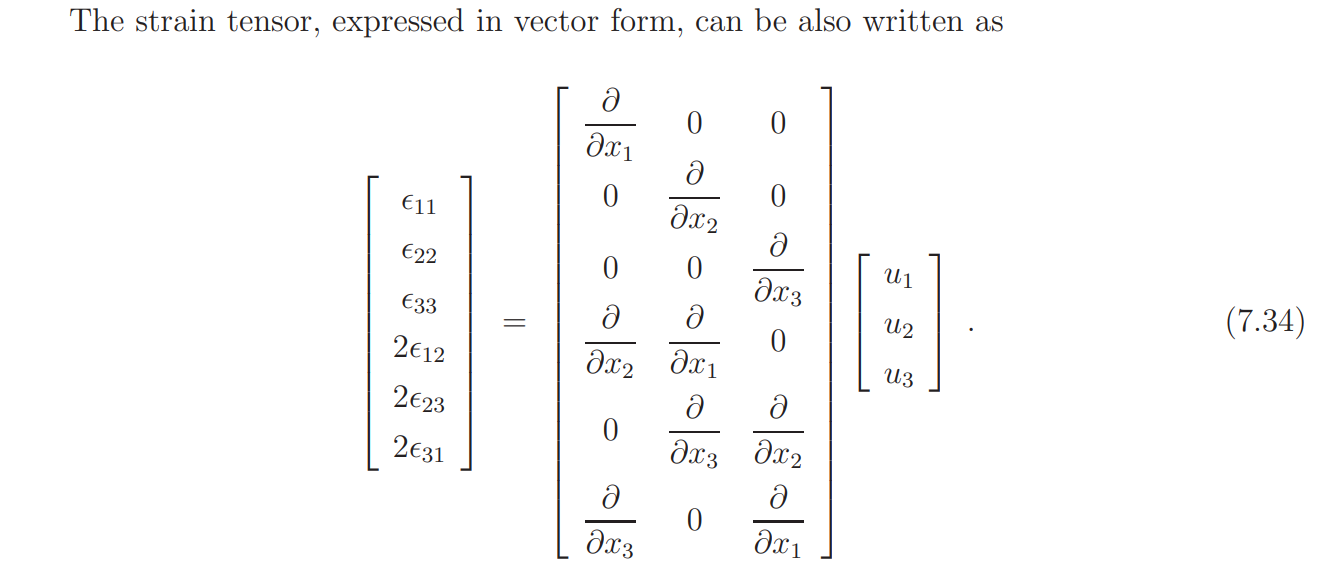

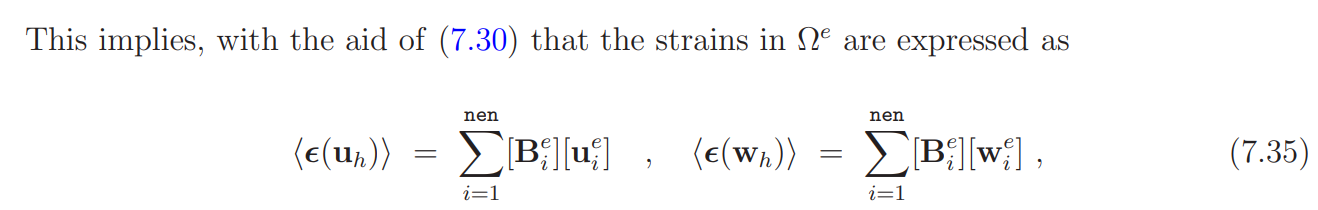

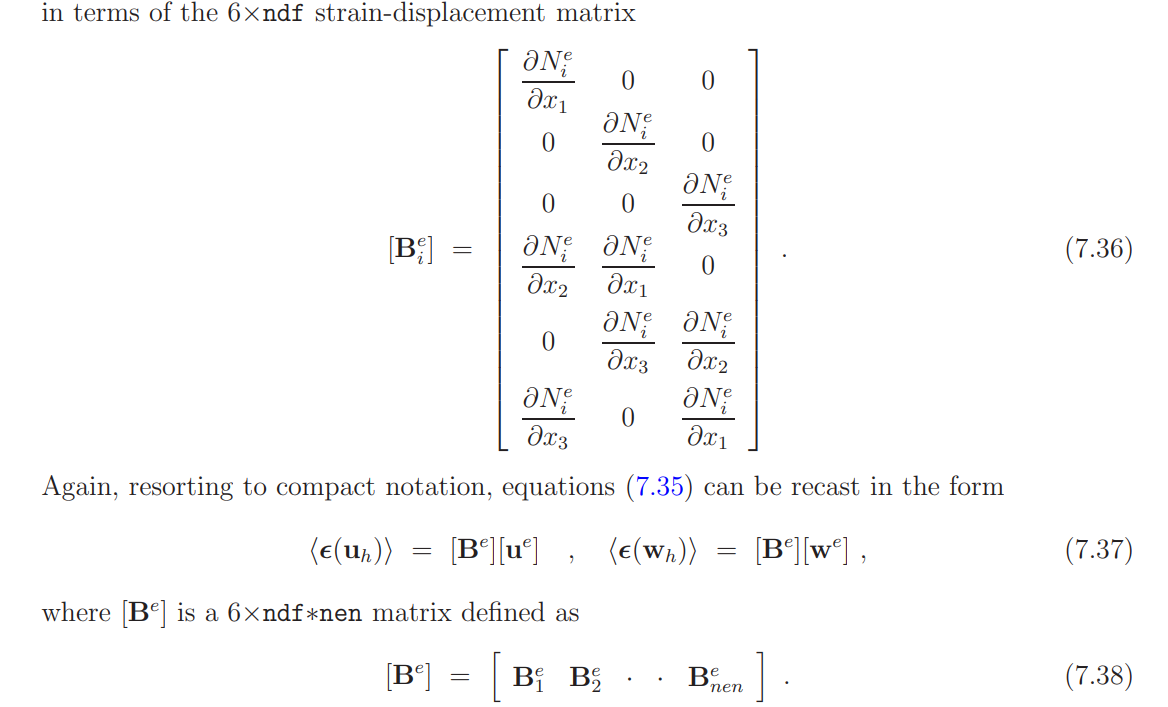

On finding the derivatives of the shape functions using isoparametric mapping - use inverse of the Jacobian

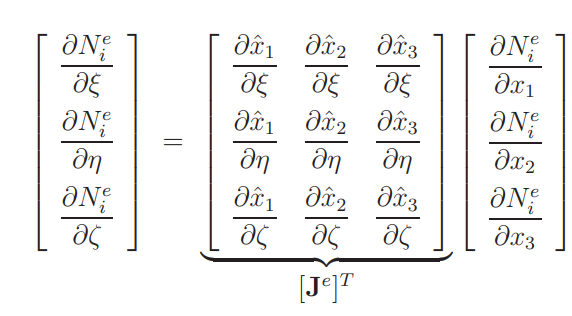

#### Element code: some x and y coordinates for an element have been inputted

nen = 4; % number of nodes in an element (implied, does not actually change)
ndf = 2; % degrees of freedom per node (implied, does not actually change)
ngauss = 2; % number of gauss points per direction (implied, does not actually change)

plain_condition = 2; % 1 for plain strain and 2 for plain stress

syms mu lambda E nu
matFun = [E == mu*(3*lambda + 2*mu)/(lambda + mu);
nu == lambda/(2*(lambda + mu))];
solution = solve(matFun,[lambda,mu]);
clear lambda mu E nu
syms E nu
lambda = solution.lambda

$$lambda = -\frac{\text{E}\,\nu }{2\,\nu^{2}+\nu -1}$$

mu = solution.mu

$$mu = \frac{\text{E}}{2\,\nu +2}$$


D = sym(zeros(3));
if plain_condition == 1
    D(1, 1) = lambda + 2*mu
    D(2, 2) = lambda + 2*mu
    D(3,3) = mu
    D(1, 2) = lambda
    D(2, 1) = lambda

elseif plain_condition == 2
    D(1, 1) = 4*mu*(lambda + mu)/(lambda + 2*mu);
    D(2, 2) = 4*mu*(lambda + mu)/(lambda + 2*mu);
    D(3,3) = mu;
    D(1, 2) =  2*lambda*mu/(lambda + 2*mu);
    D(2, 1) =  2*lambda*mu/(lambda + 2*mu);
end

matlabFunction(D,"File","D_mat","Vars",{E, nu})

ans = function_handle with value:
    @D_mat


## Pre-compute various functions for this element to reduce repeated calculations during numerical integration

syms xi eta 
syms x [4, 1] 
syms y [4, 1]
syms f_x [4, 1]
syms f_y [4, 1]
% Bilinear shape functions
N = 1/4*[(1-xi)*(1-eta), (1+xi)*(1-eta), (1+xi)*(1+eta), (1-xi)*(1+eta)];
% Derivatives of shape functions with respect to two isoparametric coordinates:
%row is isoparametric coordinate [xi, eta] and column is shape function number
dN_diso = [diff(N, xi); diff(N, eta)];

% Interpolate "global" x and y accross an element as functions of [xi, eta]
x_gl = N*x;
y_gl = N*y;

% Take derivatives once
dx_dxi = diff(x_gl, xi);
dy_dxi = diff(y_gl, xi);
dx_deta = diff(x_gl, eta);
dy_deta = diff(y_gl, eta);

% Determine Jacobian, its determinant, and inverse
J_T = [dx_dxi  dy_dxi; 
    dx_deta, dy_deta];
J_T_det = det(J_T);
J_T_inv = 1/J_T_det*[ dy_deta, -dy_dxi;
                     -dx_deta,  dx_dxi];

% Determine gradient of N with respect to natural coordinates using chain rule
dN_dnat = J_T_inv*dN_diso;

% Initiate and fill in the strain-displacement matrix 
B = sym(zeros(3,nen*ndf));
B(1, 1:2:end) = dN_dnat(1,:);
B(2, 2:2:end) = dN_dnat(2,:);
B(3, 1:2:end) = dN_dnat(2,:);
B(3, 2:2:end) = dN_dnat(1,:);

% Generate functions for easy access during numerical integration
matlabFunction(B,"File","B_el","Vars",{xi, eta, x, y});
matlabFunction(J_T_det,"File","j_el","Vars",{xi, eta, x, y});
matlabFunction(N,"File","N_gen","Vars",{xi, eta});

#### Two-point Gauss quadrature points and weights

gp = [-sqrt(1/3), sqrt(1/3)];
gw = [1, 1]; 